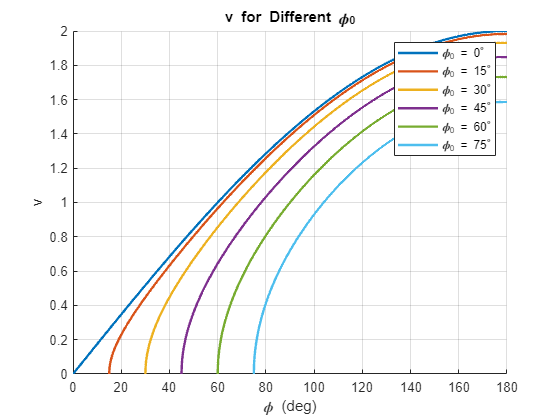

%% Different values of phi0
phi0_list = deg2rad([0 15 30 45 60 75]);

figure;
hold on;
grid on;

for k = 1:length(phi0_list)
    phi0 = phi0_list(k);
    phi = linspace(phi0, pi, 1000);

    v = sqrt(2*(cos(phi0) - cos(phi)));

    plot(rad2deg(phi), v, 'LineWidth', 1.8, ...
        'DisplayName', sprintf('\\phi_0 = %d^\\circ', round(rad2deg(phi0))));
end

xlabel('\phi (deg)');
ylabel('v');
title('v for Different \phi_0');
legend show;

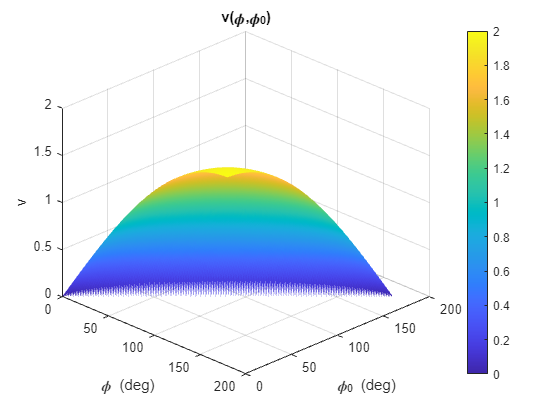


%% 3D Surface
phi0 = linspace(0, pi, 200);
phi  = linspace(0, pi, 200);

[PHI, PHI0] = meshgrid(phi, phi0);

% Only valid where phi >= phi0
V = sqrt(2*(cos(PHI0) - cos(PHI)));

% Remove invalid region
V(PHI < PHI0) = NaN;

figure;
surf(rad2deg(PHI), rad2deg(PHI0), V, 'EdgeColor', 'none');

xlabel('\phi (deg)');
ylabel('\phi_0 (deg)');
zlabel('v');
title('v(\phi,\phi_0)');
colorbar;
view(45,30);
grid on;